# Pressure, Velocity, Energy and Power

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

In fluid dynamics, understanding the link in between pressure, velocity, energy and power is essential because they are the driving mechanism of fluid flow. Pressure is closely relate to the forces exherted by the fluid, velocity measure the speed and direction of the fluid, energy is a measure of the ability of a fluid to do work, and power is a measure of the rate at which energy is transfered. In this script we will explore how these concept are related, interact and how critical they are in the design and analysis of fluid systems such as pumps, pipelines, and hydroelectric power plants.

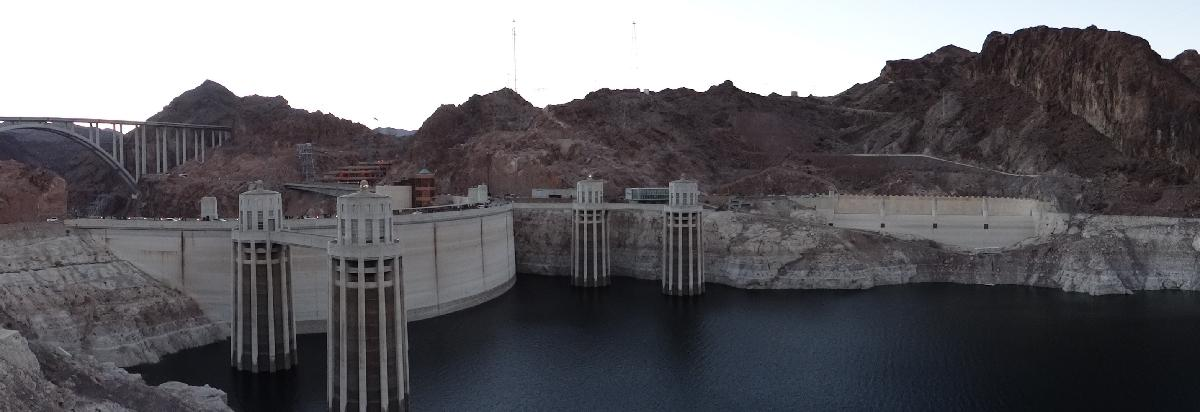

Hoover Dam intake tower from lake Mead, [USGS](https://www.usgs.gov/media/images/hoover-dam-intake-towers-panorama)

## **Before you get started**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build somgit e familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## What is pressure?

Pressure is a measure of the force that a fluid exert on the wall of container. On a microscopic scale, the fluid particles are impacting the container wall and bounce back from it. Because the fluid is composed of a very large number of particle, all of those discrete impact can be added together over time. The resulting force from this very large number of impacts the pressure, often noted $p$ or $P$. Pressure is a scalar quatity that exist in the whole fluid domain, it is dimensionally equivalent to a force per unit of surface. The total resulting force on a surface can be calculated from the pressure by using the following formula:


$$F=P\times S$$


  **Try.** Run the following function to visualize fluid particle impact on a surface

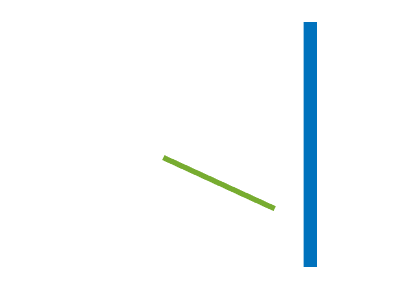

plotPressure()

### Absolute versus relative

Pressure is often referred as being absolute or relative, the absolute pressure is the pressure that was introduced previously, representing the force per unit of surface. A relative pressure is the difference of pressure between the absolute pressure and a reference pressure.


$$P_\text{absolute}=P_\text{relative} + P_\text{reference}$$


The relative pressure is often called gauge pressure.

### Units

Pressure's SI reference unit is the Pascal (Pa), named after the [Blaise Pascal](https://en.wikipedia.org/wiki/Blaise_Pascal), a French mathematician and physist from the XVII century.

  **Try. **Run the following code to create a unit system and get information about Pascals

units = symunit;
Pascals = units.Pa;
unitInfo(Pascals)


pascal - a physical unit of pressure. ['SI']

Get all units for measuring 'Pressure' by calling unitInfo('Pressure').
SI units accept all SI prefixes. For details, see SI Unit Prefixes List.



  **Try. **Following the prompt from `unitInfo`, explore all unit of pressure available

unitInfo("Pressure")


All units of dimension 'Pressure':

at - technical atmosphere
atm - standard atmosphere
Ba - barye 
bar - bar
cmH2O - centimeter of water (conventional)
cmHg - centimeter of mercury (conventional)
ftH2O - foot of water (conventional)
ftHg - foot of mercury (conventional)
inH2O - inch of water (conventional)
inHg - inch of mercury (conventional)
ksf - kip per square foot
ksi - kip per square inch
mH2O - meter of water (conventional)
mHg - meter of mercury (conventional)
mmH2O - millimeter of water (conventional)
mmHg - millimeter of mercury (conventional)
Pa - pascal ['SI']
psf - pound force per square foot
psi - pound force per square inch
pz - pieze
Torr - torr

Get the base SI units of any unit above by calling rewrite(<unit>,'SI').
SI units accept all SI prefixes. For details, see SI Unit Prefixes List.


Some of the most common units of pressure are:

- mmHg (millimeter of mercury) is used in medicine to measure the blood pressure, for example a blood pressure of 120/80 means that the systolic (while the heart pump) pressure is 120 mmHg and the diastolic (while the heart is at rest in between beats) pressure is 80 mmHg.

- mH2O (meter of water) is used to design large hydraulic system such as pipeline or hydropower plant.

- atm (atmosphere) correspond to the atmospheric pressure at sea leavel (1 atm = 101325 Pa). It has been used in chemistry as standard pressure.

- bar (bar) closest multiple of Pascal to the atmosphere (1 bar = 100000 Pa), is now used to define the standard pressure in chemistry.

- psi/psf are commonly used in as empirical unit of pressure.

 **Exercise. **Use [`unitConversionFactor`](https://www.mathworks.com/help/symbolic/unitconversionfactor.html) to compute the conversion factor between bar to Pa, atm to Pa, bar to psi and atm to psi

bar2Pa = unitConversionFactor(units.bar,units.Pa)

$$bar2Pa = 100000$$

atm2Pa = unitConversionFactor(units.atm,units.Pa)

$$atm2Pa = 101325$$

bar2psi = unitConversionFactor(units.bar,units.psi)

$$bar2psi = 14.5038$$

atm2psi = unitConversionFactor(units.atm,units.psi)

$$atm2psi = 14.6959$$

 **Exercise. **Use [`rewrite`](https://www.mathworks.com/help/symbolic/rewrite.html?searchHighlight=rewrite&s_tid=srchtitle_rewrite_1) and [`baseUnits`](https://www.mathworks.com/help/symbolic/baseunits.html?s_tid=doc_ta) to first convert Pascals in the base SI units, and then into N and m.

Pascals = rewrite(Pascals, baseUnits("SI"))

$$Pascals = \frac{\mathrm{kg}}{m\,s^{2}}$$

Pascals = rewrite(Pascals, [units.m units.N])

$$Pascals = \frac{N}{m^{2}}$$

 **Reflect**. Units of pressure such as Pascals correspond to Newton per square meter, wich correspond to unit of force per unit of surface.

## What is energy? 

In a fluid, energy refers to the ability of a fluid to produce work. It can take various forms, such as kinetic energy, which is associated with the motion of the fluid particles, or potential energy, wich is associated with the position of the fluid particles or its pressure. 

  **Try. **Following the prompt from `unitInfo`, explore all unit of pressure available

unitInfo("Energy")


All units of dimension 'Energy':

erg - erg
eV - electronvolt
E_h - Hartree energy 
J - joule ['SI']
kpm - kilopond meter
Wh - watt hour
Ws - watt second

Get the base SI units of any unit above by calling rewrite(<unit>,'SI').
SI units accept all SI prefixes. For details, see SI Unit Prefixes List.



XXX Check in books for more

## What is power?

Power refers to the rate at which energy is transferred. It is typically measured in units of energy per unit of time, such as Watts (W) or horsepower (hp).

  **Try. **Following the prompt from `unitInfo`, explore all unit of pressure available

unitInfo("Power")


All units of dimension 'Power':

HP_DIN - metric horsepower (DIN 66036)
HP_E - electrical horsepower
HP_I - mechanical horsepower
HP_UK - British imperial horsepower
poncelet - poncelet
PS_DIN - horsepower (DIN 70020)
PS_SAE - net horsepower (SAE J1349)
W - watt ['SI']

Get the base SI units of any unit above by calling rewrite(<unit>,'SI').
SI units accept all SI prefixes. For details, see SI Unit Prefixes List.



**Reflect. **Multiple dimension of horsepower.

XXX Check in books for more

## **Application: Wind turbine**

In this section, we are going to analyze the performance of a wind turbine by:

- Applying the [Control Volume](matlab:open('./ManOnTheMoon.mlx')) method

- Solving a simple power balance of the system

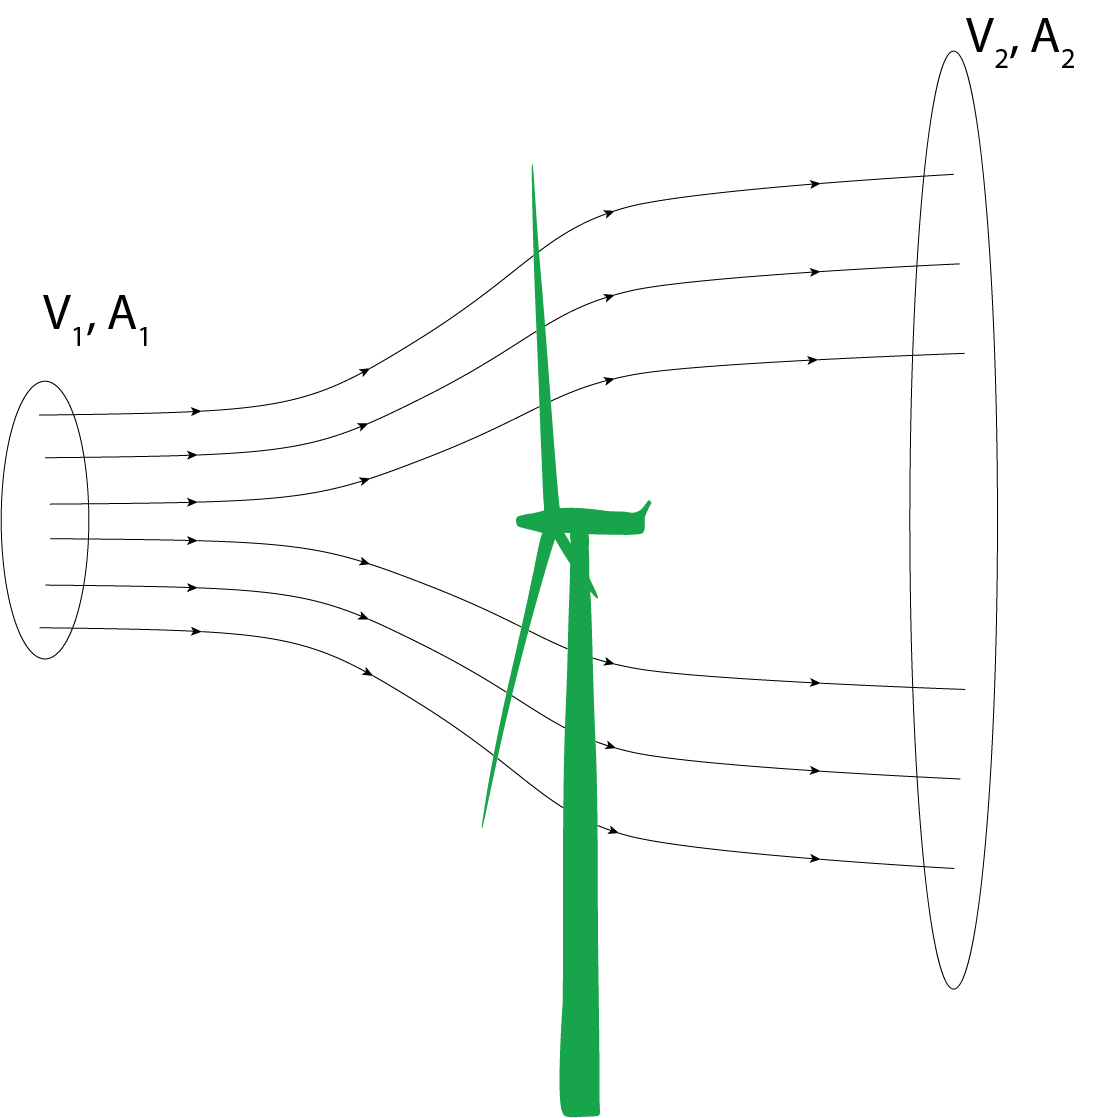

### **Control Volume**

We consider the control volume as describe as in the previous figure. All the mass flow coming in the control volume volume through the surface A, must exit the control volume through surface B. Therefore we can write the following mass flow equilibrium:


$$\rho S_A v_A = \rho S_B v_B = \rho S_t v_t = \dot{m}$$


where $\rho$ is the density, $(S_A,S_B,S_t)$ are the arar of surface A, B and the area of the turbine, and $(v_A,v_B,v_t)$ are the velocity of the flow through the surface A, B and the turbine itself.

  **Try. **Define the parameter of the problem.

syms rho S_A S_B S_t v_A v_B v_t
m_dot = rho*S_t*v_t

$$m\_dot = S_{t}\,\rho \,v_{t}$$

The momentum conservation equation is th


$$\underbrace{\frac{\partial}{\partial t}\int_{CV}\rho\vec{u} \; dV}_\text{Acceleration}
+
\underbrace{\int_{CS}(\vec{u}\cdot\vec{n})\rho\vec{u} \; dS}_\text{Thrust}
=
\sum\vec{F}$$


We are considering the flow to be at steady-state, so the derivative with respect to time is equal to 0. There is no radial flow, so all the air entering the turbine upstream is exiting the turbine downstream. Therefore, we are left with:


$$\int_\text{upstream}(\vec{v}\cdot\vec{n})\rho\vec{v} \; dS
+
\int_\text{downstream}(\vec{v}\cdot\vec{n})\rho\vec{v} \; dS
=
\vec{F}_\text{turbine\rightarrow air}$$


The upstream term can be expressed as:


$$\int_\text{upstream}(\vec{v}\cdot\vec{n})\rho\vec{v} \; dS
=
-\dot{m}\vec{v_A}$$


 **Exercise. **Complete the expression of $F_\text{turbine\rightarrow air}$ in `F_ta`, using it to compute F_at $XXX$. You can use the simplify function to make the results more readable.

F_ta = - m_dot*v_A + m_dot*v_B;
F_at = simplify(- F_ta)

$$F\_at = S_{t}\,\rho \,v_{t}\,\left(v_{A}-v_{B}\right)$$


$$dE = F dx$$



$$P = \frac{dE}{dt} = F\frac{dx}{dt} = Fv$$


P_at = simplify(F_at * v_t)

$$P\_at = S_{t}\,\rho \,{v_{t}}^{2}\,\left(v_{A}-v_{B}\right)$$

### **Power Balance**


$$P_\text{air\rightarrow turbine} = P_A - P_b \quad\quad (\clubsuit)$$


 **Exercise. **Write the power of the fluid going through surface A and surface B in `P_A` and `P_B.`

P_A = 1/2*m_dot*v_A^2;
P_B = 1/2*m_dot*v_B^2;

 **Exercise. **Write $(\clubsuit)$ in `PowerBalance.`

PowerBalance = P_at == P_A - P_B

$$PowerBalance = S_{t}\,\rho \,{v_{t}}^{2}\,\left(v_{A}-v_{B}\right)=0.5000\,S_{t}\,\rho \,{v_{A}}^{2}\,v_{t}-0.5000\,S_{t}\,\rho \,{v_{B}}^{2}\,v_{t}$$

 **Exercise. **Solve the power balance to express $v_t$ as a function of $v_A$ and $v_B$, save the results in v_Sol

v_Sol = solve(PowerBalance, v_t)

$$v\_Sol = \left(\begin{array}{c} 0\\ 0.5000\,v_{A}+0.5000\,v_{B} \end{array}\right)$$

**Reflect. **

v_Sol = v_Sol(2)

$$v\_Sol = 0.5000\,v_{A}+0.5000\,v_{B}$$

 **Exercise. **Solve

P_at = subs(P_at,v_t, v_Sol)

$$P\_at = S_{t}\,\rho \,{\left(0.5000\,v_{A}+0.5000\,v_{B}\right)}^{2}\,\left(v_{A}-v_{B}\right)$$

XXX Check answer and iterate on it

 **Exercise. **Solve

P_0 = 1/2*rho*S_t*v_A^3

$$P\_0 = 0.5000\,S_{t}\,\rho \,{v_{A}}^{3}$$

 **Exercise. **Solve

% Declare the efficient eta = P_at/P_0
eta = P_at/P_0

$$eta = \frac{2\,{\left(0.5000\,v_{A}+0.5000\,v_{B}\right)}^{2}\,\left(v_{A}-v_{B}\right)}{{v_{A}}^{3}}$$

% Substitute v_B by x*v_A, this should rewrite the equation as a function
% of x = v_B/v_a
syms x
eta = simplify(subs(eta, v_B, x*v_A))

$$eta = -0.5000\,\left(x-1\right)\,{\left(x+1\right)}^{2}$$

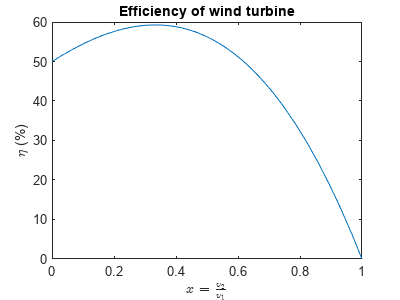

% Plotting function
fplot(x,100*eta,[0 1])
xlabel("$x=\frac{v_2}{v_1}$",Interpreter="latex")
ylabel("\eta (%)")
title("Efficiency of wind turbine")

## Bernoulli's Principle

## Definition

The Bernoulli equation is a fundamental tool of fluid dynamisist that describes the relationship between pressure, velocity and elevation change in the fluid. This equation is named after the Swiss mathematician, Daniel Bernoulli, who first formulated it in 1738. The Bernoulli equation states that the total energy of a fluid system is constant along a streamline:


$$P+
\frac{1}{2}\rho v^2+
\rho g h= \text{Constant} \qquad(\star)$$


  **Try. **Check if density is consistent with pressure?

dynamicPressureUnits = units.kg/units.m^3*(units.m/units.s)^2;
checkUnits(dynamicPressureUnits == units.Pa)

ans = struct with fields:
    Consistent: 1
    Compatible: 1

 **Exercise. **Similarly check that the gravitational potential term's unit is consistent with a pressure units.

gravitationalPotentialUnits = units.kg/units.m^3*units.m/units.s^2*units.m;
checkUnits(gravitationalPotentialUnits == units.Pa)

ans = struct with fields:
    Consistent: 1
    Compatible: 1

where P represents the pressure of the fluid, $\rho$ its density, $v$ its velocity, $g$ gravitational acceleration and $h$ the elevation. From a non-expert point of view, the conservation of "energy" promised by the definition is not evident. In order to highlight the energy term, we can multiply both side of $(\star)$ by the volume $V$ (careful with the definition of the fluid's velocity and its volume $v \neq V$):


$$PV+
\frac{1}{2}\rho V v^2+
\rho V g h= \text{Constant} \qquad(\star)\times V$$


with $\rho V = m$, the fluid mass, we obtain:


$$PV+
\frac{1}{2}mv^2+
m g h= \text{Constant} \qquad(\star)\times V$$


- $PV$    is the pressure potential energy

- $\frac{1}{2}mv^2$    is the kinetic energy

- $mgh$    is the gravitational potential energy

So the $(\star)$ is in fact the conservation of the total energy along a stream line. We should now apply the Bernoulli equation along a streamline of a free flowing fluid.

  **Try.** Use the slider below to visualize a streamline in between point A and point B of a fluid flow with an elevation difference.

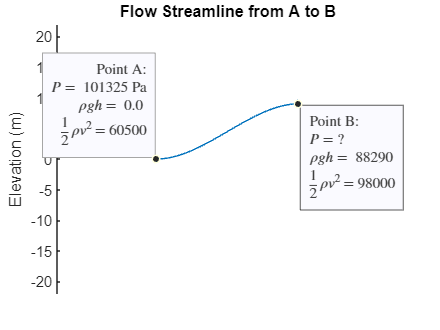

dh = 9;
vA = 11;
vB = 14;
rho = 1000;
plotStreamline(dh, vA, vB, rho)

The Bernoulli equation $(\star)$ is often writen in the different form, called the hydraulic head form:


$$\frac{P}{\rho g} + \frac{v^2}{2 g} + h = H_0=\text{Constant}$$


The equation stays the same in nature, but the different term are all writen in unit of length instead of being writen in unit of pressure. This form is used in the case of hydraulic flow (flow of water) where the density of the fluid is high and any change in elevation impact the flow. While dealing with gases, the $(\star)$ is preferred as the effect of gravity are often neglected.

Because all of the term in $(\star)$ are dimensionally equivalent to a pressure, we are defining different pressures:

- $P$ is the static pressure.

- $\frac{1}{2}\rho v^2$    is the dynamic pressure, it is pressure that is exerted by the fluid dur to its motion. It is also known as "impact pressure". 

- $\rho g h$ is the hydrostatic pressure

The total pressure is defined as the sum of the static, dynamic and hydrostatic pressure:


$$P_\text{total} = P_\text{static} + \frac{1}{2}\rho v^2 + \rho g h$$


Therefore, Bernoulli's equation can be read as the conservation of total pressure along a streamline. Finally, the stagnation pressure is defined as:


$$P_\text{stagnation} = P_\text{static} + \frac{1}{2}\rho v^2$$


The stagnation pressure is equivalent to the pressure that the fluid would have if it came to "stagnation" (a.k.a. $v=0$). It is obtained from applying $(\star)$ as:


$$ P_\text{static} + \frac{1}{2}\rho v^2 = P_\text{stagnation} + \frac{1}{2}\rho 0^2$$


### **Application: Pitot tube**

Pitot tubes are apparatus that measure the flow velocity. It is commonly used on aircraft to measure the airspeed and the water speed for boats.

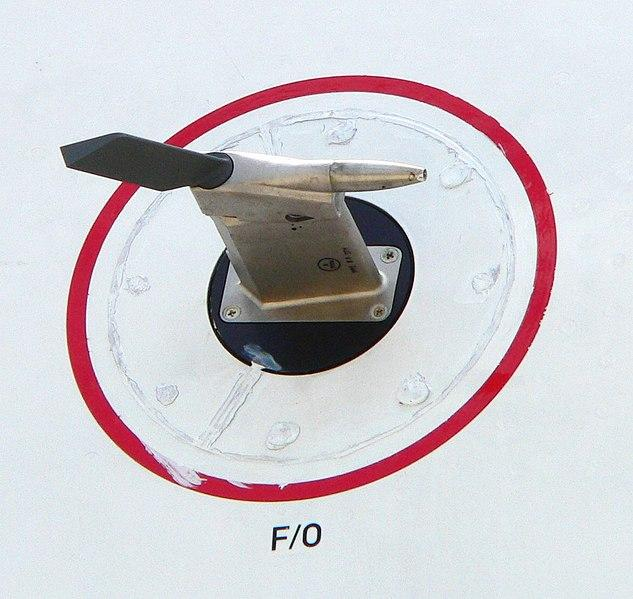

An Airbus A380's pitot tube, [wikimedia](https://commons.wikimedia.org/wiki/File:Airspeed_p1230157.jpg)

There is multiple type of Pitot tube, in this section we will study a Pitot-static tube, which present two opening, one in the front and one on the side. The tube is oriented directly facing the 

figure
axis equal
axis off
x = [0 1.5   1.5    0  0.15  1.6 1.6 0.35 0.35  1.5   1.5   0.3   0.3 0.15];
y = [0 0   -0.1 -0.1 -0.2 -0.2 0.1  0.1  0.075 0.075 0.025 0.025 0.1  0.1] + 0.05;
patch(x,y,'b',"FaceAlpha",0.3)
hold on
scatter(-0.3,0,30,'filled',"r")
scatter(1.5,0,30,'filled',"r")
line([-0.3 1.5],[0 0])
hold off

 **Exercise.** Identify the pressure in measure at point A and point B

% checkPressurePitot(A="None",B="None");
 

Exercise. Express the free-stream velocity as a function of $\Delta p = p_t - p_s$

% Declare the parameter of the problem
syms pt ps rho u dp
% Define the equation defining the relation between pt and ps
eqn = pt == ps + (rho*u^2/2);
% Solve this equation for u, the velocity
u = solve(eqn, u,"PrincipalValue",true)
% substitue pt-ps for dp
u = subs(u, pt-ps, dp)
% Plot the velocity based on the measure difference of pressure

### **Application: Lift generation around airfoil**

In this section we will be studying the lift generation by a NACA-2412 airfoil. This airfoil presents a 2% camber at with the max camber at 40% of the chords and 12% thickness. 

[lc,lu,ll] = NACAXXXX(12,2,40);

For more information about NACA airfoil and the NACAXXXX function run the following command in your command window:

Let's consider a plane flying at a cruise speed of 135 kts (knots).

  **Try.** Run the following code to create to convert the cruise speed in (m/s).

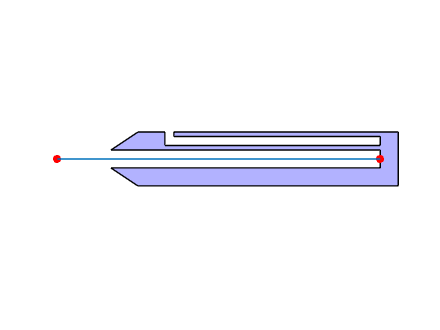

cruiseSpeed = 135 * units.kts;
cruiseSpeed = unitConvert( CruiseSpeed, units.m/units.s)

The upstream velocity is considered to be equal to the atmospheric pressure (101325 Pa) and the air density is considered to be 1.14 kg/m3. 

upstreamPressure = 101325*units.Pa;
rhoAir = 1.14*units.kg/units.m^3;

  **Try.** Define the velocity along the upper and lower surface

upperVelocity = 118*units.m/units.s;
lowerVelocity = 32*units.m/units.s;

 **Exercise. **using Bernoulli's principle, compute the pressure along the upper and lower surface.

upperPressure = simplify(upstreamPressure + 1/2*rhoAir*cruiseSpeed^2 - 1/2*rhoAir*upperVelocity^2)

$$u = \frac{1.4142\,\sqrt{\mathrm{pt}-\mathrm{ps}}}{\rho^{0.5000}}$$

lowerPressure = simplify(upstreamPressure + 1/2*rhoAir*cruiseSpeed^2 - 1/2*rhoAir*lowerVelocity^2)

 **Exercise. **Set a larger pressure along the lower surface than along the upper surfaces, 

$$u = \frac{1.4142\,\sqrt{\mathrm{dp}}}{\rho^{0.5000}}$$

 **Exercise. **Set a larger pressure along the upper surface than along the lower surfaces, 

## Glossary

**Streamline: **In fluid dynamics, the mathematical definition of a streamline is the line in a flow that is tangent to the velocity vector at every point. Physically, it represents the path that a small, frictionless particle would follow if it were to flow in this fluid.

## Helper Functions

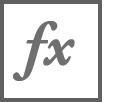**plotStreamline**`(dh, v1, v2, rho)`

- `dh`

- `v1`

- `v2`

- `rho`

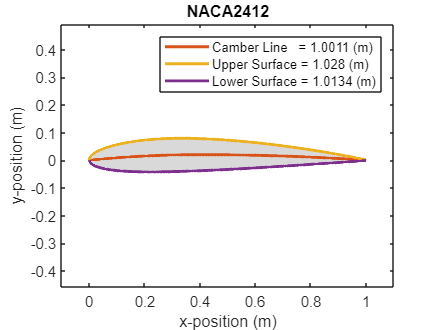

function plotStreamline(dh, v1, v2, rho)

arguments
    dh (1,1) {mustBeReal,mustBeInRange(dh,-20,20)} = 0
    v1 (1,1) {mustBeReal,mustBeGreaterThanOrEqual(v1,0.0)} = 0.0
    v2 (1,1) {mustBeReal,mustBeGreaterThanOrEqual(v2,0.0)} = 0.0
    rho (1,1) {mustBeReal,mustBeGreaterThan(rho,0.0)} = 1000.0
end    


$$cruiseSpeed = 69.4500\,\frac{m}{s}$$

    % Define the path from A to B:
    xl = linspace(0,1,100);
    yl = -dh*(2*xl.^3-3*xl.^2);

    % Create the figure:
    figure
    ax = axes;
    
    % Plot A:
    s = scatter(ax,0,0,30,'filled',SeriesIndex=1);

$$upperPressure = 9.6138e+04\,\frac{\mathrm{kg}}{m\,s^{2}}$$

    s.DataTipTemplate.DataTipRows    = dataTipTextRow("Point A:", [], "auto");

$$lowerPressure = 1.0349e+05\,\frac{\mathrm{kg}}{m\,s^{2}}$$

    s.DataTipTemplate.DataTipRows(2) = dataTipTextRow("$P = $",  [101325], "%10.0f Pa");
    s.DataTipTemplate.DataTipRows(3) = dataTipTextRow("$\rho g h = $", [rho*9.81*0], "%10.1f ");
    if v1 > 0.0
        s.DataTipTemplate.DataTipRows(4) = dataTipTextRow("$\frac{1}{2}\rho v^2$ = ", [0.5*rho*v1^2], "auto");
    end
    d = datatip(s);
    d.Interpreter = "latex";
    d.Location = "northwest";
    hold on

    % Plot B:
    s = scatter(ax,1,dh, 'filled',SeriesIndex=1);
    s.DataTipTemplate.DataTipRows    = dataTipTextRow("Point B:", [], "auto");
    s.DataTipTemplate.DataTipRows(2) = dataTipTextRow("$P = ?$",  [], "auto");
    s.DataTipTemplate.DataTipRows(3) = dataTipTextRow("$\rho g h = $", [rho*9.81*dh], "auto");
    if v1 > 0.0
        s.DataTipTemplate.DataTipRows(4) = dataTipTextRow("$\frac{1}{2}\rho v^2$ = ", [0.5*rho*v2^2], "auto");
    end
    d = datatip(s);
    d.Location = "southeast";
    d.Interpreter = "latex";
    
    
    % Plot Free Path:
    plot(ax,xl,yl)
    hold off

    % Set plot limit, title, etc.:
    xlim([-0.7 1.7])
    ylim([-22 22])
    title("Flow Streamline from A to B")
    ylabel("Elevation (m)")
    ax.XAxis.Visible = "off";
    
end

function plotPressure()
    figure
    ax = axes;
    axis off
    xlim(ax,[0 1.2])
    ylim(ax,[-1 1])
    l = line(ax,[1 1],[-1 1],"LineWidth",10);
    dt = 0.1;
    x = [0 2*rand-1];
    v = [1 2*rand-1] - x;
    v = v / norm(v);
    
    h = animatedline(ax,'MaximumNumPoints',7,"LineWidth",4,"Color",ax.ColorOrder(5,:));
    addpoints(h, x(1), x(2))
    for i = 1:200
        if l.Color == ax.ColorOrder(3,:)
            l.Color = ax.ColorOrder(1,:);
        end
        x = x + dt*v;
        if x(1) > 1.0
            x(1) = 1.0;
            v(1) = -v(1);
            l.Color = ax.ColorOrder(3,:);
        end
        if x(1) < 0.0
            x = [0 2*rand-1];
            v = [1 2*rand-1] - x;
            v = v / norm(v);
            clearpoints(h)
        end
        addpoints(h, x(1),x(2)) 
        drawnow
    end
end

[⇦ Return to the navigation page](matlab:open('./Overview.html'))

Copyright 2023 The MathWorks™, Inc